## 1) Indice phi nella tabella di contingenza di dimensione 2x2

Sia data la Tabella di contingenza 1.5 riportata a p. 54.

Calcolare l'indice $\phi$ tramite la formula


$$\phi=\frac{n_{11}  n_{22} -n_{12}n_{21}}{\sqrt{n_{1.}n_{2.}n_{.1}n_{.2}}}$$
 

Verificare che l'indice $\phi$ può essere ottenuto come coefficiente di correlazione tra i due fenomeni X e Y.

1) Utilizzare le formule della varianza e covarianza delle due variabili in una tabella di dimensione *IxJ*

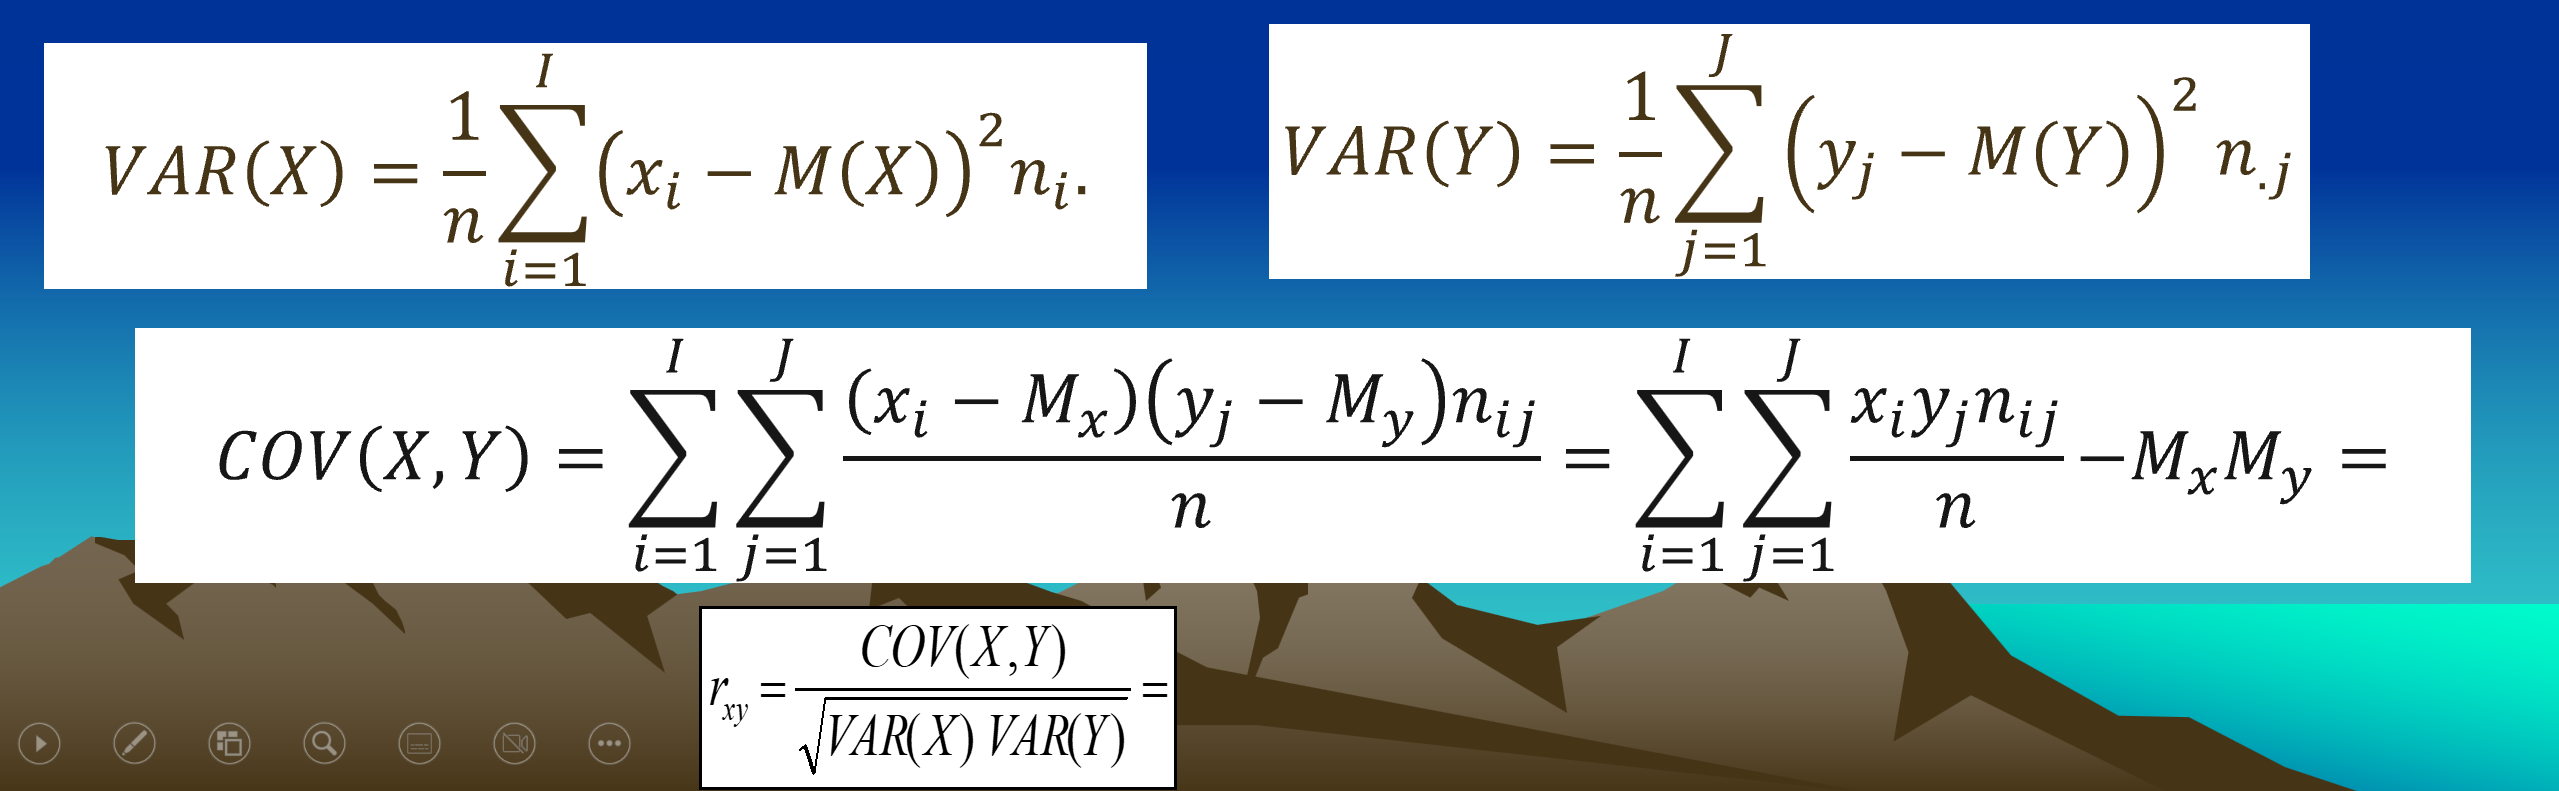

2) Mostrare tutti i passaggi del calcolo della correlazione utilizzando la funzione `GUIcorr` di FSDA toolbox

3) Partendo dalla tabella di contingenza, tramite la funzione `crosstab2datamatrix `di FSDA toolbox, ricostruire la matrice dei dati di partenza `X`. Sulla matrice dei dati di partenza calcolare il coefficiente di correlazione lineare e verificare l'uguaglianza con l'indice $\phi$ ottenuto tramite le formule precedenti.

4) Moltiplicare ogni colonna della matrice `X` per un numero positivo a piacere. Aggiungere alle colonne della matrice `X` un numero qualsiasi (positivo o negativo) ed illustrare come cambia il valore del coefficiente di correlazione lineare (l'indice $\phi$) dopo questa trasformazione.

5) Moltiplicare ogni colonna della matrice `X` per un numero casuale generato dalla distribuzione uniforme nell'intervallo [0 100]. Aggiungere ad ogni colonna della matrice `X` un numero generato dalla distribuzione T di Student con 2 gradi di libertà. Discutere come cambia  il valore del coefficiente di correlazione lineare (l'indice $\phi$) dopo questa trasformazione.

6) Cambiare di segno entrambe le colonne della matrice X e calcolare il nuovo coefficiente di correlazione lineare. Quale nuovo valore si ottiene?

% Calcolo indice phi
N=[87 188;
    42 406];
% n=numero di unità statistiche del campione.
n=sum(N,"all");
% sumc (1x2)= frequenze marginali di colonna
sumc=sum(N,1);

% sumr (2x1)= frequenze marginali di riga
sumr=sum(N,2);

phi=(N(1,1)*N(2,2)-N(1,2)*N(2,1))/sqrt(prod(sumr)*prod(sumc));
disp(['Il valore dell''indice \phi è ' num2str(phi)])

Il valore dell'indice \phi è 0.28227



% Senza perdita generalità condifico le modalità Sì/No dei due fenomeni con
% i numeri 1 e 0
x=[1;0];
y=x';
% Calcolo Media di X 
% (fenomeno dicotomico che assume modalità 0 e 1 con frequenze sumr(1) e sumr(2))
Mx=sum(x.*sumr)/n;
% Calcolo Varianza di X  
Varx=sum((x-Mx).^2.*sumr)/n;

% Calcolo Media di Y 
My=sum(y.*sumc)/n;
% Calcolo Varianza di Y  
Vary=sum((y-My).^2.*sumc)/n;

% Calcolo covarianza tra X e Y
covxy=sum((x*y).*N,'all')/n-Mx*My;
rxy=covxy/(sqrt(Varx*Vary));

disp(['Indice phi ottenuto come coefficiente di correlazione lineare ='  num2str(rxy)])

Indice phi ottenuto come coefficiente di correlazione lineare =0.28227


% Calcolo della correlazione utilizzando la funzione GUIcorr
% Costruisco la table partendo dall'array 2.
nam=["1" "0"];
Ntable=array2table(N,"VariableNames", nam,"RowNames",nam)

Ntable = 2×2 table
         1      0 
         __    ___

    1    87    188
    0    42    406


disp(Ntable)

         1      0 
         __    ___

    1    87    188
    0    42    406



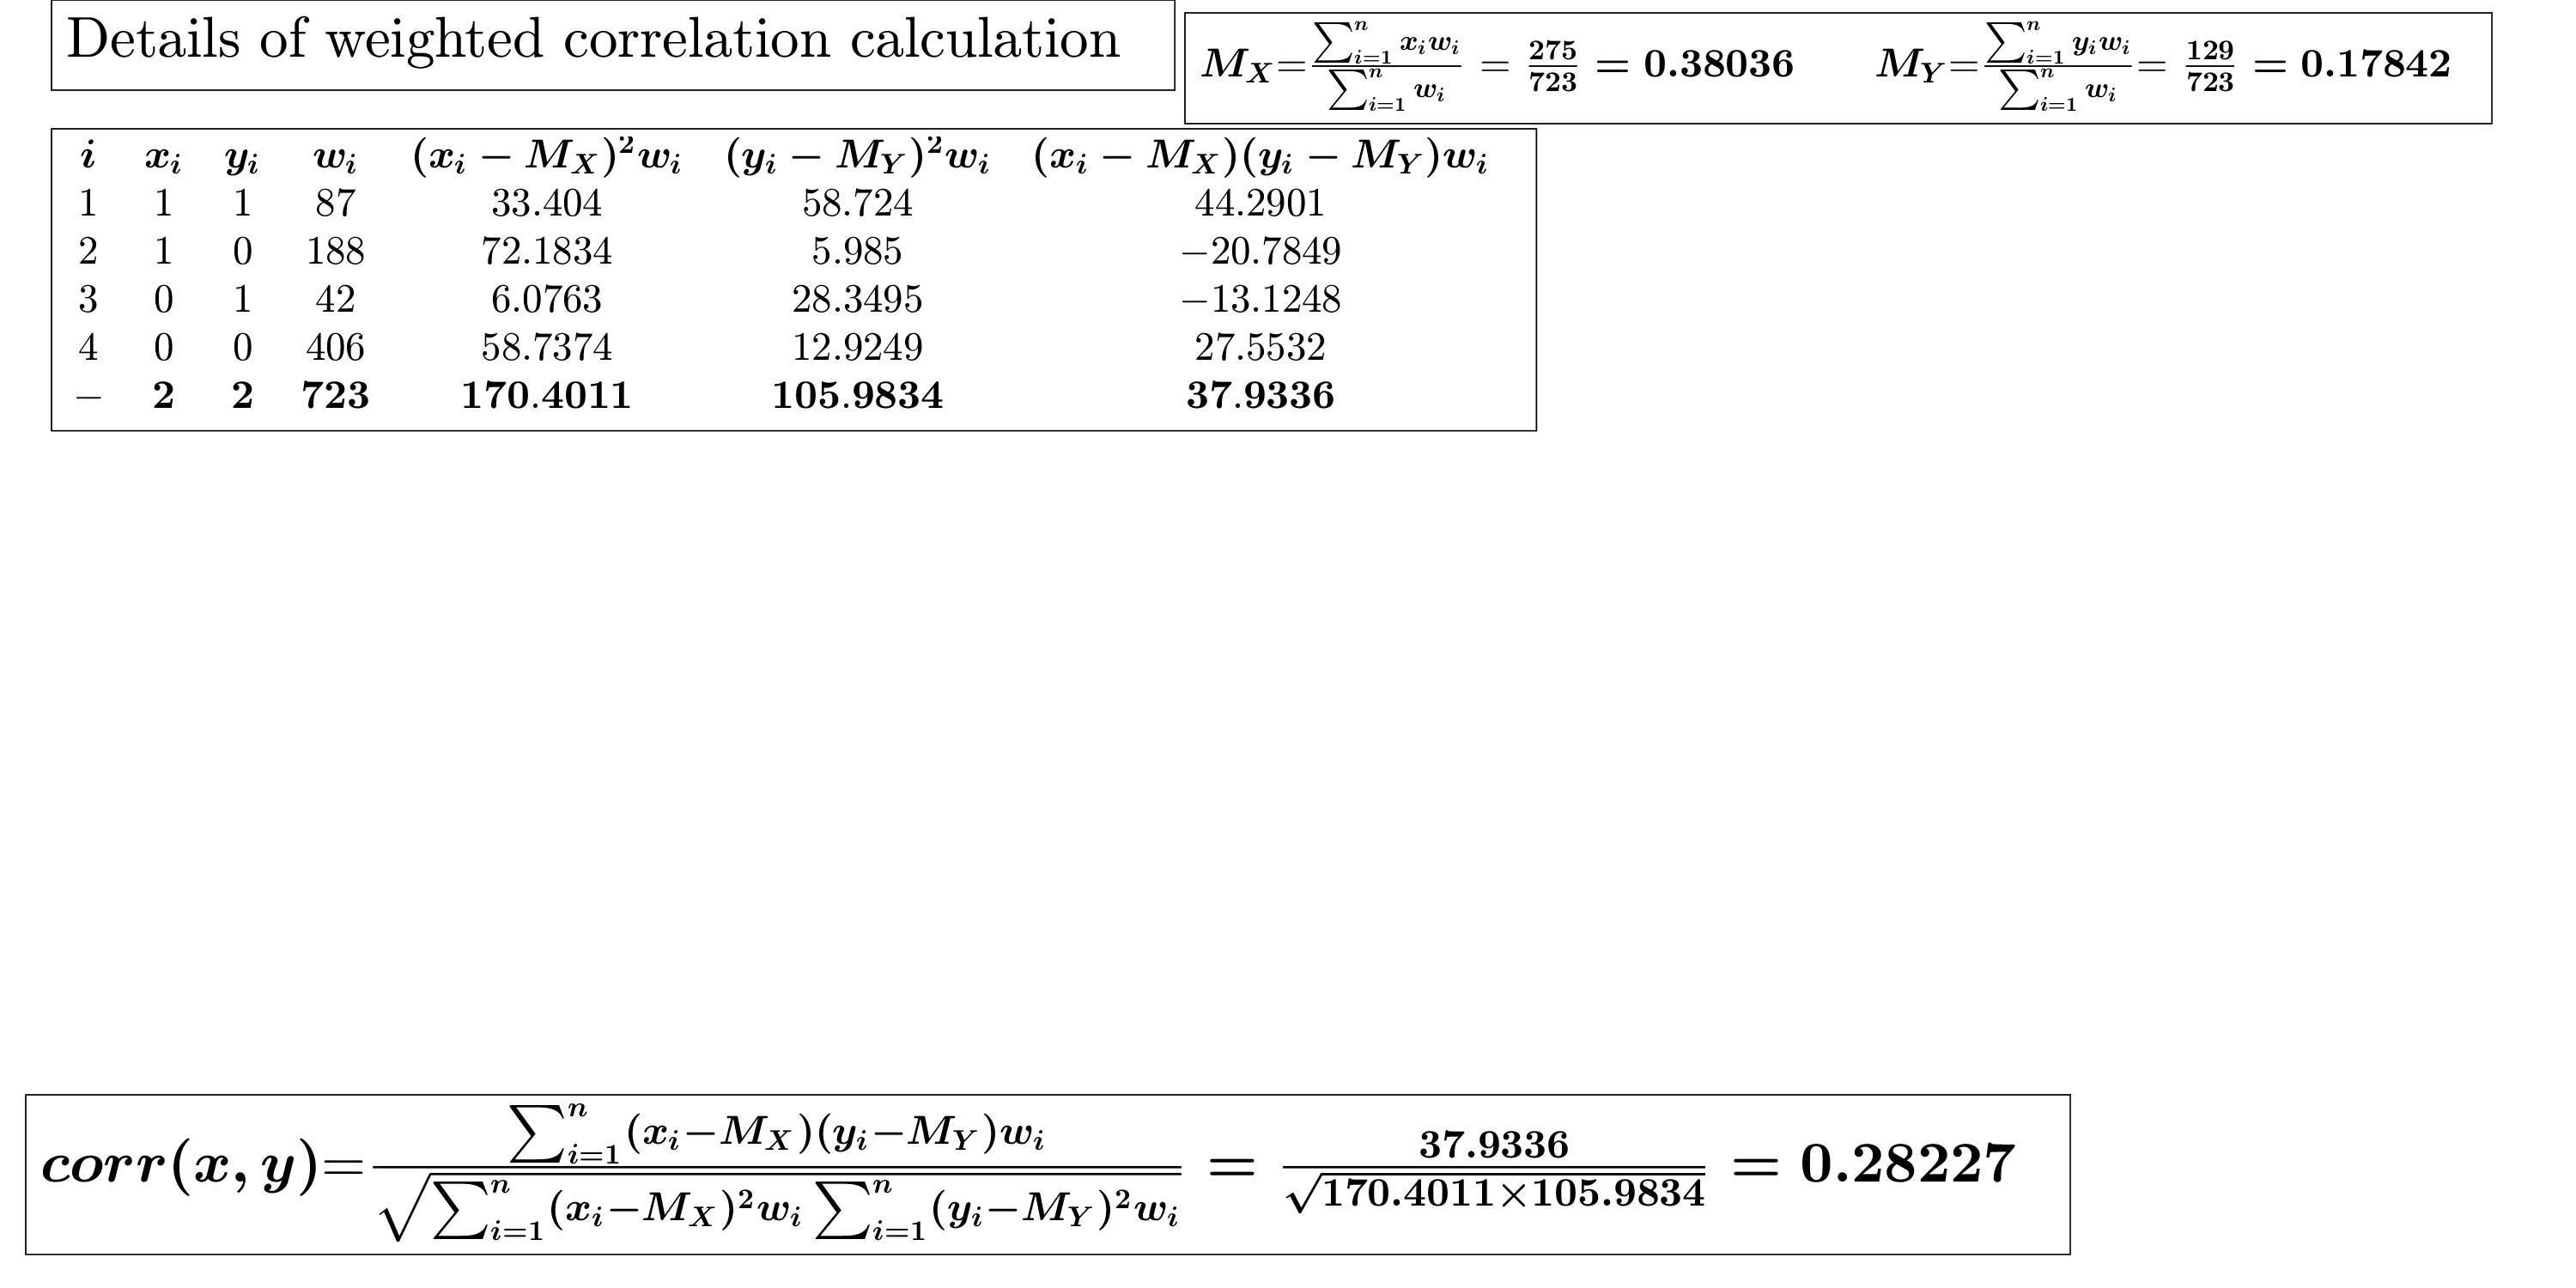

ans = struct with fields:
    data: [5×7 table]
    corr: 0.2823


GUIcorr(Ntable)

Ricostruzione della matrice originaria X che ha generato la tabella di contingenza N 

X=crosstab2datamatrix(N);
% La matrice originaria X presenta n righe (in questo caso 723 righe).
% sono 87 le righe che presentano la coppia di modalità (1,1)
% ...
% Sono 406 le righe che presentano la coppia di modalità (0,0)
disp('Calcolo del coefficiente di correlazione lineare partendo dalla matrice X')

Calcolo del coefficiente di correlazione lineare partendo dalla matrice X


disp(corr(X(:,1),X(:,2)))

    0.2823



Il coefficiente di correlazione lineare è invariante per trasformazioni lineari crescenti di una o delle due variabili, di conseguenza la codifica con 1,0 poteva essere cambiata con la codifica in 100,50 oppure 12312323424355,234245 oppure con 123,2 per X e 345345,5345 per Y ed il valore della correlazione non sarebbe cambiato.

Di seguito andiamo a verificare empiricamente questa proprietà del coeff. di correlazione lineare.

Moltiplicare ogni colonna della matrice X per un numero positivo a piacere. Aggiungere alle colonne della matrice X un numero qualsiasi (positivo o negativo) ed illustrare come cambia il valore del coefficiente di correlazione lineare (l'indice $\phi$) dopo questa trasformazione.

X1=X.*[123 345345]+[3424352 -765456754];
disp(['Calcolo del coefficiente di correlazione lineare' ...
    ' partendo da una trasformazione lineare crescente della matrice X'])

Calcolo del coefficiente di correlazione lineare partendo da una trasformazione lineare crescente della matrice X


disp(corr(X1(:,1),X1(:,2)))

    0.2823



Moltiplicare ogni colonna della matrice X tramite un numero casuale generato dalla distribuzione uniforme nell'intervallo [0 100]. Aggiungere ad ogni colonna della matrice X un numero generato dalla distribuzione T di Student con 2 gradi di libertà. Discutere come cambia  il valore del coefficiente di correlazione lineare (l'indice $\phi$) dopo questa trasformazione.

X2=X.*unifrnd(0,100,1,2)+trnd(2,1,2);
disp(['Calcolo del coefficiente di correlazione lineare' ...
    ' partendo da una trasformazione lineare crescente della matrice X'])

Calcolo del coefficiente di correlazione lineare partendo da una trasformazione lineare crescente della matrice X


disp(corr(X2(:,1),X2(:,2)))

    0.2823



 Cambiare di segno entrambe le colonne della matrice X e calcolare il nuovo coefficiente di correlazione lineare. Quale nuovo valore si ottiene?

disp(['Calcolo del coefficiente di correlazione lineare' ...
    ' sulla matrice X cambiata di segno'])

Calcolo del coefficiente di correlazione lineare sulla matrice X cambiata di segno


disp(corr(-X(:,1),-X(:,2)))

    0.2823



Ancora una volta la correlazione non cambia.